Specify the initial state estimate to have zero velocity.

x = 0.2;
y = 0.3;
initialState = [x;0;y;0];
KF = trackingKF('MotionModel','2D Constant Velocity','State',initialState);

disp(KF.StateTransitionModel);

     1     1     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1



disp(KF.MeasurementModel);

     1     0     0     0
     0     0     1     0



Create the measured positions from a constant-velocity trajectory.

vx = 0.2;
vy = 0.1;
T  = 0.5;
pos = [0:vx*T:2;0:vy*T:1]';
pos = pos + 0.05*randn(size(pos));

Predict and correct the state of the object.

for k = 1:size(pos,1)
    pstates(k,:) = predict(KF,T);
    cstates(k,:) = correct(KF,pos(k,:));
end

Plot the tracks.

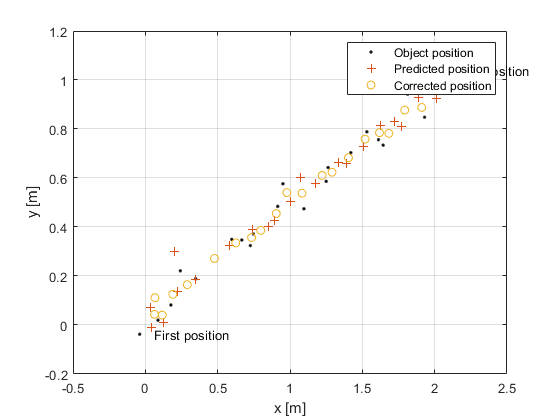

plot(pos(:,1),pos(:,2),'k.', pstates(:,1),pstates(:,3),'+', ...
    cstates(:,1),cstates(:,3),'o')
xlabel('x [m]')
ylabel('y [m]')
grid
xt  = [x-2 pos(1,1)+0.1 pos(end,1)+0.1];
yt = [y pos(1,2) pos(end,2)];
text(xt,yt,{'First measurement','First position','Last position'})
legend('Object position', 'Predicted position', 'Corrected position')